# C&PE 778 Homework 03                                 William Powers 2025

#### ***1. ****Formulate the following problem as a linear program. Then use GAMS and CPLEX to solve it, and explain the meaning of the result including the marginal cost values. Finally, solve the problem by hand using the simplex method,  showing each tableau you use.*

The Very Green Lawn company makes different types of fertilizer from two raw materials, nitrate and phosphate.  The current inventory has 80 metric tons of nitrate and 50 metric tons of phosphate. The mixture ratios and net profit obtained by producing and selling each of the three types of fertilizer are given in the table below. Assuming no more raw materials can currently be purchased, some raw materials may be left in inventory, and enough demand exists such that all fertilizer produced can be sold, determine how much of each type of fertilizer should be produced in order to maximize the profit.

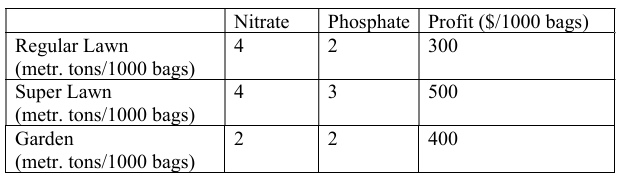

## Numerical Solution:

***Standardizing: ***Denoting $x_1$ as thousands of bags of regular lawn fertilizer, $x_2$ as thousands of bags of super lawn fertilizer, and $x_3$ as thousands of bags of garden fertilizer, our goal is to maximize profit


$$\max_{\mathbf{x}} \{ z=300x_1 + 500x_2 + 400x_3 \}$$


subject to the nitrate and phosphae requirements for each fertilizer are less than or equal to the companies finite supply as well as are not using negative quantities (no physical meaning).


$$4x_1 + 4x_2 + 2x_3 \le 80$$



$$2x_1 + 3x_2 + 2x_3 \le 50$$



$$x_1, x_2, x_3 \ge 0$$


Becuase this problem contains in equalities, it must be first transformed into standard form by introducing slack variables $s_1$ and $s_2$


$$4x_1 + 4x_2 + 2x_3 + s_1 = 80$$



$$2x_1 + 3x_2 + 2x_3 + s_2 = 50$$



$$x_1, x_2, x_3, s_1, s_2 \ge 0$$


The equation is now of the form

$\max_{\mathbf{x}} \{ \mathbf{c^Tx} \}$  s.t.  $\mathbf{Ax} = \mathbf{b}$,  $\mathbf{x} \ge 0$

where

$\mathbf{A} = 
\left[
\begin{array}{cc}
4 & 4 & 2 & 1 & 0\\
2 & 3 & 2 & 0 & 1
\end{array}
\right]



$,  $\mathbf{b} = 
\left[
\begin{array}{cc}
80 & 50
\end{array}
\right]^T



$,  $\mathbf{c} = 
\left[
\begin{array}{cc}
300 & 500 & 400 & 0 & 0
\end{array}
\right]^T



$,  $\mathbf{x} = 
\left[
\begin{array}{cc}
x_1 & x_2 & x_3 & s_1 & s_2
\end{array}
\right]^T



$

***MATLAB: ***The problem is solved below using matlabs linear programming method `linprog(*)`.

c = -[300; 500; 400; 0; 0]; % maximize profit -> minimize -profit
Aeq = [4 4 2 1 0; 2 3 2 0 1];
beq = [80; 50];
lowBound = [0; 0; 0; 0; 0];

opts = optimoptions('linprog','Algorithm','dual-simplex','Display','none');
[x, fval, exitflag, output, lambda] = linprog(c, [], [], Aeq, beq, lowBound, [], opts);

fprintf('Production (thousand bags): Regular=%.4g, Super=%.4g, Garden=%.4g\n', x(1:3));

Production (thousand bags): Regular=0, Super=0, Garden=25


fprintf('Max profit: $%.2f\n', -fval);

Max profit: $10000.00


fprintf('Remaining slack [nitrate, phosphate] (metric tons); [%.2f, %.2f]\n', x(4), x(5));

Remaining slack [nitrate, phosphate] (metric tons); [30.00, 0.00]


## Analytical Solution:

Given that the problem was converted to standard form in the previous section, the first step is to form an iniital basic feasible solution (BFS) by setting all decision variables to zero: $x_1=x_2=x_3=0$ corresponding to $z=0$. Next the initial simplex tableau is formed with initial basis: $\{ s_1 \ s_2 \}$

***Pivot 1: ***The entering variable is choosen as the most negative in the $z$ row $\rightarrow x_2$. Using the ratio test on the elements of column $x_2$: $80/4=20$ and $50/3=16.7$, the smallest is choosen as the leaving variable $\rightarrow$ $s_2$, thus the new basis is $\{ s_1 \ x_2\}$. Row operation $R_2 \leftarrow R_2 / 3$ is performed to make the pivot $=1$ and row operations $R_1 \leftarrow R_1 - 4R_2$ and $R_3 \leftarrow R_3 + 500R_2$ are performed to zero $x_2$ in the equations above and below row (2).

***Pivot 2: ***The entering variable is choosen as the most negative in the $z$ row $\rightarrow$$x_3$. Using the ratio test on this column, we see that $s_1$ will leave the basis, thus the bew basis is: $\{ x_3 \ x_2 \ s_3\}$. Row operation $R_1 \leftarrow (2/3)R_1$ is performed to make the pivot $=1$ and row operations $R_2 \leftarrow R_2 - (2/3) R_1$ and $R_x \leftarrow R_z + (200/3)R_1$ are performed to zero $x_3$ in rows (2) and $z$. This leaves the tableau as

***Final Solution: ***As there are no negatives in the $z$ row, the current solution is optimal with basis $\{x_3 \ x_2 \}$, vertex $(0, 10, 20)$, objective value of 10000, and slack value of $(0, 0)$. This physically corresponds to a profit of $10000 making 10000 bags of super grass fertilizer and 20000 bags of garden fertilizer without over using the companies finite resources.

***Comparison: ***The MATLAB and hand–calculated simplex solutions select different vertices of the feasible region, but both yield the same maximum profit. This happens because the objective function is parallel to one of the constraint boundaries, creating a line of optimal solutions rather than a single unique vertex. The MATLAB solution however results in a remaining ntirate value of 30 metric tons corresponding to less resources being used for the same profit thus it is a physically more meaningful solution.